# Unit Testing

The goal is to test the graphical App of the Parking Meter system.

Copyright 2023 The MathWorks, Inc.

## 1. Clean Session

Clear all remaining variables, figures and timers:

clear variables; close all; clc;
try
  stop(timerfind);
  delete(timerfind);
catch
  disp('No timers are running.');
end

No timers are running.


Add needed classes to the import list:

import matlab.unittest.TestRunner;
import matlab.unittest.TestSuite;
import matlab.unittest.plugins.TestReportPlugin;
import matlab.unittest.plugins.CodeCoveragePlugin;

## 2. Test Runner and Test Suite

Build test runner and test suite allowing to customize how the suite is run and which tests to run.

runner = TestRunner.withTextOutput;

Test report format:

reportName = 'Report';
reportType = 'docx';
switch (reportType)
  case 'docx'
    reportPlugin = TestReportPlugin.producingDOCX([reportName '.' reportType],...
                                                  'IncludingPassingDiagnostics',true,...
                                                  'IncludingCommandWindowText',true);
  case 'html'
    reportPlugin = TestReportPlugin.producingHTML([reportName '.' reportType],...
                                                  'IncludingPassingDiagnostics',true,...
                                                  'IncludingCommandWindowText',true);
  case 'pdf'
    reportPlugin = TestReportPlugin.producingPDF([reportName '.' reportType],...
                                                 'IncludingPassingDiagnostics',true,...
                                                 'IncludingCommandWindowText',true);
  otherwise
    error('Unsupported file type for a report.');
end
runner.addPlugin(reportPlugin);

Coverage report:

coveragePlugin = CodeCoveragePlugin.forFile('..\Components\ParkingMeterAutoTestGUI.mlapp');
runner.addPlugin(coveragePlugin);

Create the test suite from the defined test class

classSuite = TestSuite.fromClass(?TestApp);

## 3. Initialization

Preparing the parking meter system for the tests:

global UNIT_TESTING; %#ok<GVMIS> 
% Set to true if the MATLAB unit testing API is used, otherwise always false
UNIT_TESTING = true;
% Close any potential running instance of the low-level application
if (system('taskkill /F /im ParkingMeterProject.exe /im cmd.exe &') ~= 0)
  fprintf('No running instance of the low-level application has been detected.\n');
end

No running instance of the low-level application has been detected.


% Call the low-level MATLAB code of the application in a separate process
fprintf('Starting the low-level application instance...\n');

Starting the low-level application instance...


system('..\\C_project\\ParkingMeterProject\\x64\\Release\\ParkingMeterProject.exe&');

## 4. Run Tests

Running TestApp
--> Processing the test case #1: Straight Ticket Purchase...


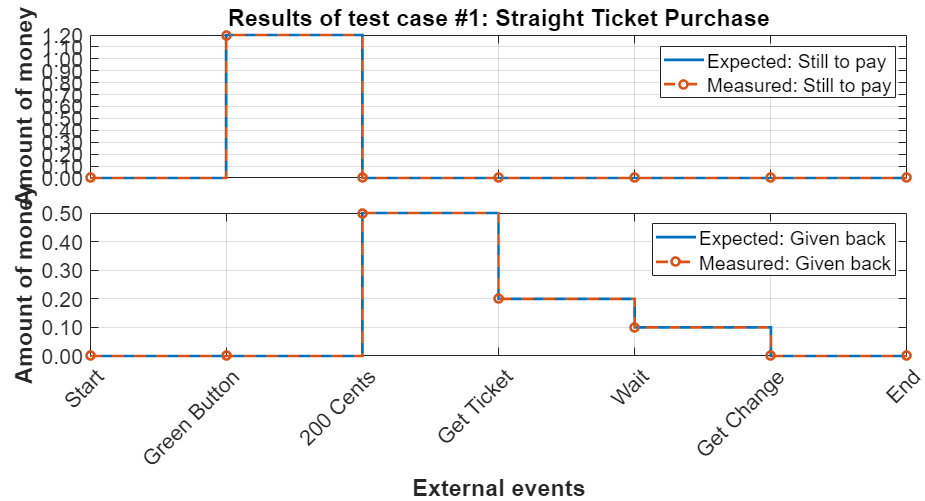


[Terse] Diagnostic logged (2023-04-12 17:47:52):
Figure saved to:
--> C:\Users\sebas\AppData\Local\Temp\90415fe1-a524-4df2-93ad-4c2ee19d658b\Figure_ee926a2f-e913-426c-ae91-74e9219b3fab.fig
--> C:\Users\sebas\AppData\Local\Temp\90415fe1-a524-4df2-93ad-4c2ee19d658b\Figure_ee926a2f-e913-426c-ae91-74e9219b3fab.png
--------------------------------------------------------------------------------
.--> Processing the test case #2: Biggest Change On Ticket Purchase...


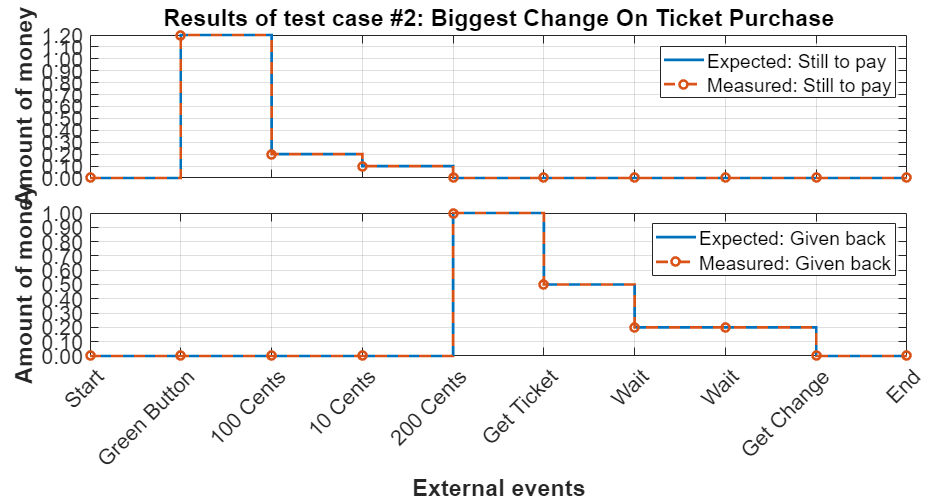


[Terse] Diagnostic logged (2023-04-12 17:48:13):
Figure saved to:
--> C:\Users\sebas\AppData\Local\Temp\90415fe1-a524-4df2-93ad-4c2ee19d658b\Figure_da1e9629-dc72-4359-bb59-1697ca6c38ee.fig
--> C:\Users\sebas\AppData\Local\Temp\90415fe1-a524-4df2-93ad-4c2ee19d658b\Figure_da1e9629-dc72-4359-bb59-1697ca6c38ee.png
--------------------------------------------------------------------------------
.--> Processing the test case #3: Cancel Ticket Purchase...


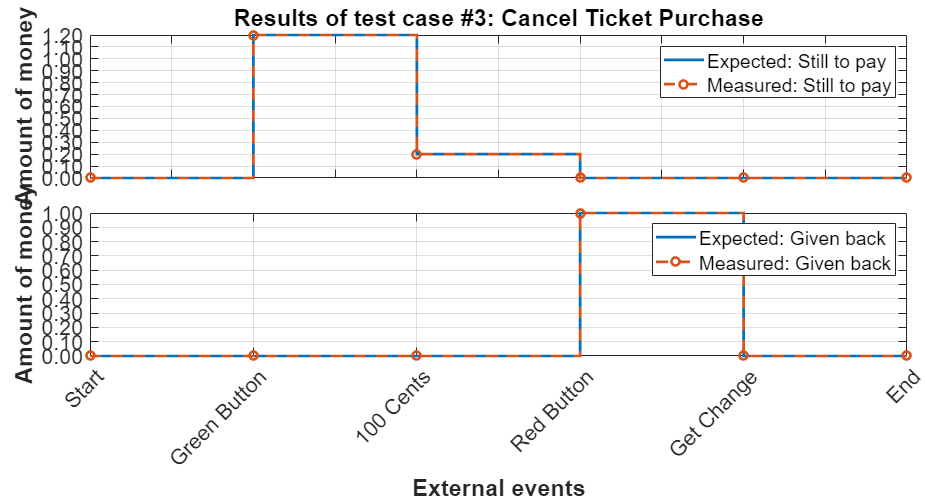


[Terse] Diagnostic logged (2023-04-12 17:48:31):
Figure saved to:
--> C:\Users\sebas\AppData\Local\Temp\90415fe1-a524-4df2-93ad-4c2ee19d658b\Figure_035487aa-3468-4a9e-9170-e6f096988729.fig
--> C:\Users\sebas\AppData\Local\Temp\90415fe1-a524-4df2-93ad-4c2ee19d658b\Figure_035487aa-3468-4a9e-9170-e6f096988729.png
--------------------------------------------------------------------------------
.--> Processing the test case #4: 50 Cents Incremental Ticket Purchase...


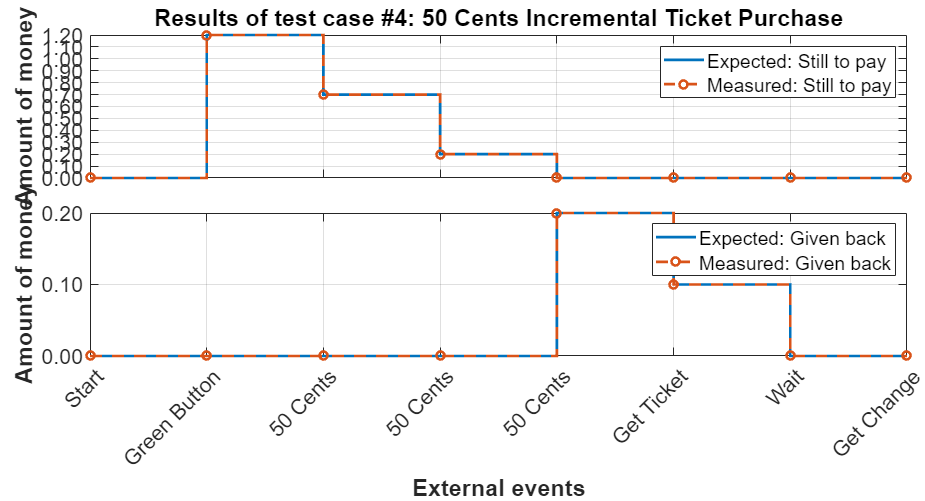


[Terse] Diagnostic logged (2023-04-12 17:48:57):
Figure saved to:
--> C:\Users\sebas\AppData\Local\Temp\90415fe1-a524-4df2-93ad-4c2ee19d658b\Figure_f7ea9225-1769-4aff-960c-9d9f1668918e.fig
--> C:\Users\sebas\AppData\Local\Temp\90415fe1-a524-4df2-93ad-4c2ee19d658b\Figure_f7ea9225-1769-4aff-960c-9d9f1668918e.png
--------------------------------------------------------------------------------
.--> Processing the test case #5: 20 Cents Incremental Ticket Purchase...


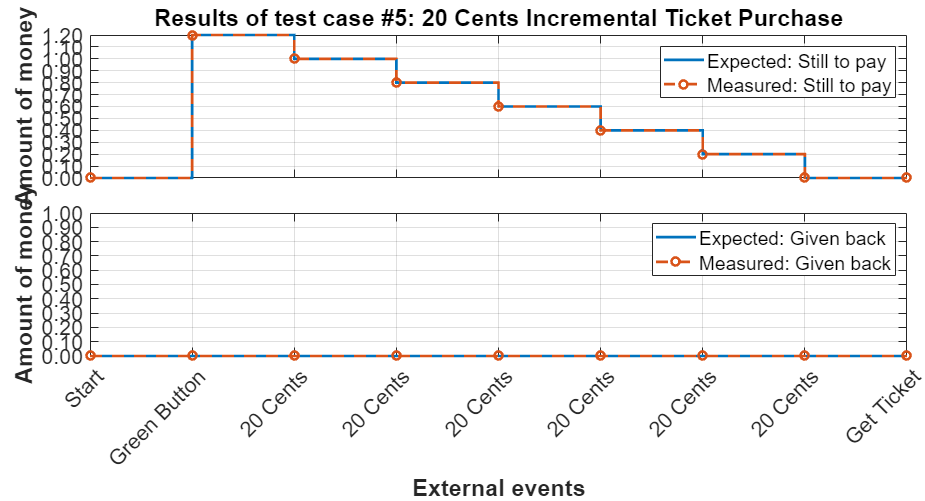


[Terse] Diagnostic logged (2023-04-12 17:49:26):
Figure saved to:
--> C:\Users\sebas\AppData\Local\Temp\90415fe1-a524-4df2-93ad-4c2ee19d658b\Figure_c155bb37-5b6d-41d5-b711-0a984e2ff22c.fig
--> C:\Users\sebas\AppData\Local\Temp\90415fe1-a524-4df2-93ad-4c2ee19d658b\Figure_c155bb37-5b6d-41d5-b711-0a984e2ff22c.png
--------------------------------------------------------------------------------
.--> Processing the test case #6: 10 Cents Incremental Ticket Purchase...


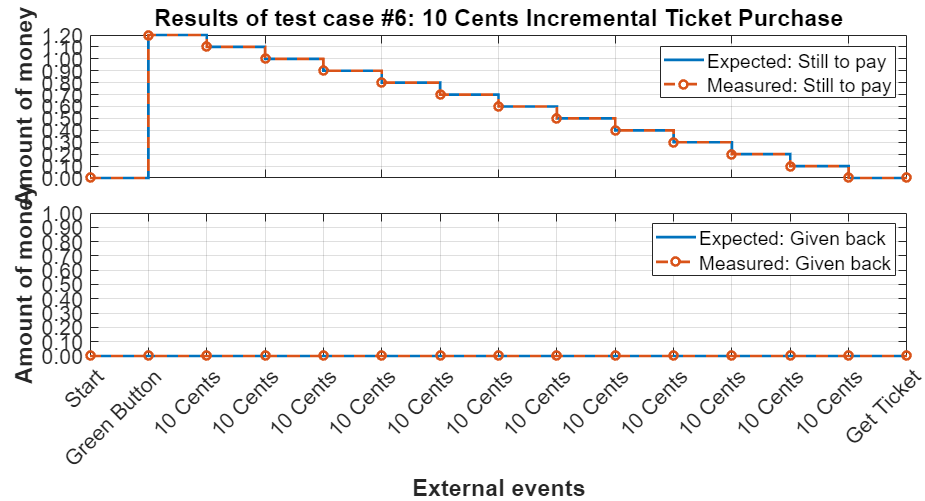


[Terse] Diagnostic logged (2023-04-12 17:50:08):
Figure saved to:
--> C:\Users\sebas\AppData\Local\Temp\90415fe1-a524-4df2-93ad-4c2ee19d658b\Figure_4da6f0a4-b779-4ad0-85dd-a3d6243cf680.fig
--> C:\Users\sebas\AppData\Local\Temp\90415fe1-a524-4df2-93ad-4c2ee19d658b\Figure_4da6f0a4-b779-4ad0-85dd-a3d6243cf680.png
--------------------------------------------------------------------------------
.--> Processing the test case #7: Fully Empty And Reload CashBox...


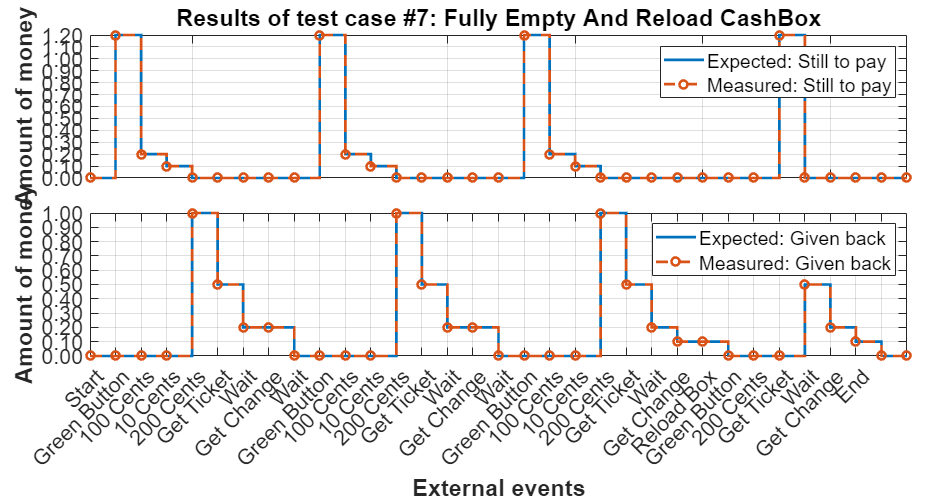


[Terse] Diagnostic logged (2023-04-12 17:51:07):
Figure saved to:
--> C:\Users\sebas\AppData\Local\Temp\90415fe1-a524-4df2-93ad-4c2ee19d658b\Figure_aaf216b8-ffb4-4443-b20c-3db5628bb527.fig
--> C:\Users\sebas\AppData\Local\Temp\90415fe1-a524-4df2-93ad-4c2ee19d658b\Figure_aaf216b8-ffb4-4443-b20c-3db5628bb527.png
--------------------------------------------------------------------------------
.--> Processing the test case #8: Switch Off The Low Level Application...


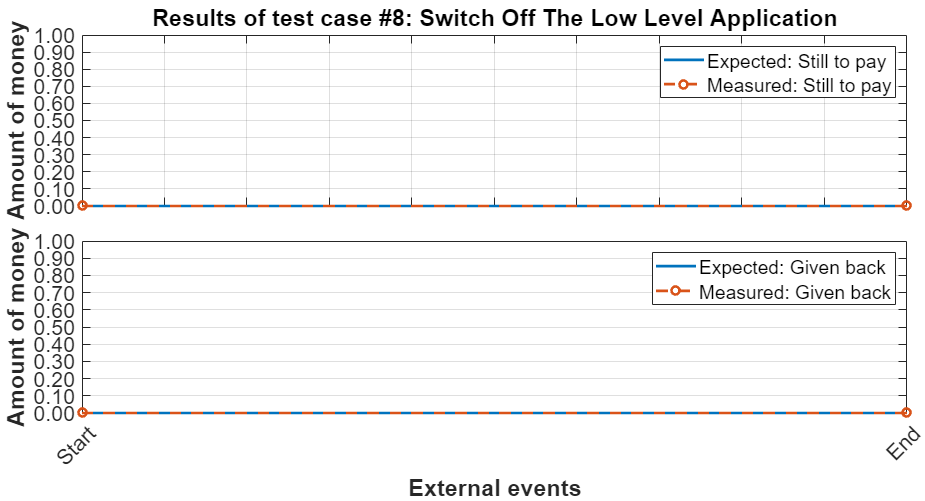


[Terse] Diagnostic logged (2023-04-12 17:51:20):
Figure saved to:
--> C:\Users\sebas\AppData\Local\Temp\90415fe1-a524-4df2-93ad-4c2ee19d658b\Figure_52253f9d-4622-4fb8-aaf2-1b8961990293.fig
--> C:\Users\sebas\AppData\Local\Temp\90415fe1-a524-4df2-93ad-4c2ee19d658b\Figure_52253f9d-4622-4fb8-aaf2-1b8961990293.png
--------------------------------------------------------------------------------
.
Done TestApp
__________

Generating test report. Please wait.
    Preparing content for the test report.
    Adding content to the test report.
    Writing test report to file.
Test report has been saved to:
 D:\GitHub\C_Code_Integration\MATLAB\Work\Report.docx
MATLAB code coverage report has been saved to:
 C:\Users\sebas\AppData\Local\Temp\tp9c9cc59b_d9e2_41d3_8036_89008874fea1\index.ht

% Call the unit testing framework for automated testing
results = runner.run(classSuite);

% Close the running instance of the low-level application
system('taskkill /F /im ParkingMeterProject.exe /im cmd.exe &');

## 5. Results Summary

disp(results.table);

                             Name                             Passed    Failed    Incomplete    Duration      Details   
    ______________________________________________________    ______    ______    __________    ________    ____________

    {'TestApp/testCase_StraightTicketPurchase'           }    true      false       false        17.743     {1×1 struct}
    {'TestApp/testCase_BiggestChangeOnTicketPurchase'    }    true      false       false        21.398     {1×1 struct}
    {'TestApp/testCase_CancelTicketPurchase'             }    true      false       false        18.876     {1×1 struct}
    {'TestApp/testCase_050CentsIncrementalTicketPurchase'}    true      false       false        24.161     {1×1 struct}
    {'TestApp/testCase_020CentsIncrementalTicketPurchase'}    true   